# **Kinematics**

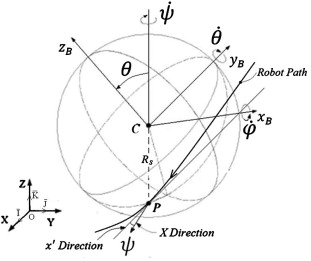

syms X(t) Y(t);
% y′ is the line of nodes for nutation angle θ measured from vertical to the axis of symmetry
syms theta(t)
syms dpsi(t) dtheta(t) dphi(t); % precession, nutation, spin
syms gamma(t) beta(t);
syms r_i R_s;
i = [1 0 0]; j = [0 1 0]; k = [0 0 1];
dX = diff(X); dX2 = diff(X,2);
dY = diff(Y); dY2 = diff(Y,2);
db = diff(beta); db2 = diff(beta,2);
dg = diff(gamma); dg2 = diff(gamma,2);
sb = sin(beta); sg = sin(gamma);
cb = cos(beta); cg = cos(gamma);

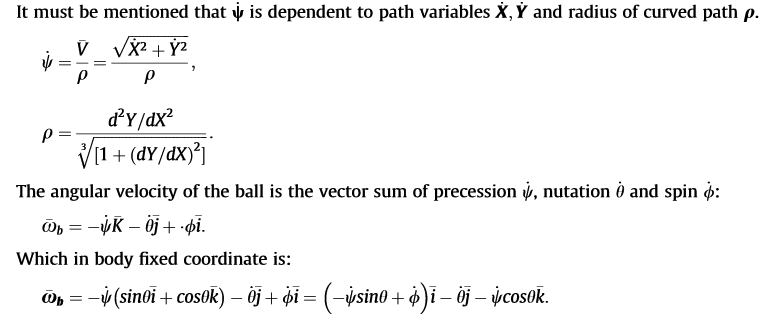

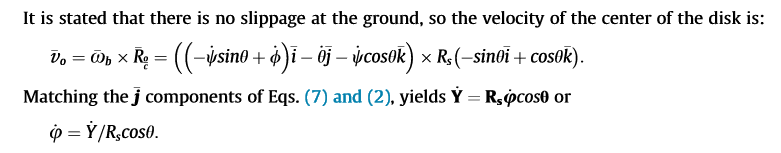

% precession
V_hat = sqrt(dX^2 + dY^2);
rho = (dY2/dX2) / (1 + (dY/dX)^2)^(1/3);
dpsi = V_hat / rho;
% nutation
dtheta = diff(theta);
% spin
dphi = dY / R_s * cos(theta);

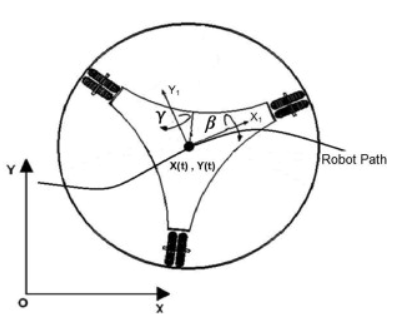

% TODO Define beta and gamma
% The angle is the angle of lifting for inner mass, around the y1 axis, 
% which causes the robot to move forward or backward. Also, angle β about x1 axis causes robot to move in curvi-linear path. 

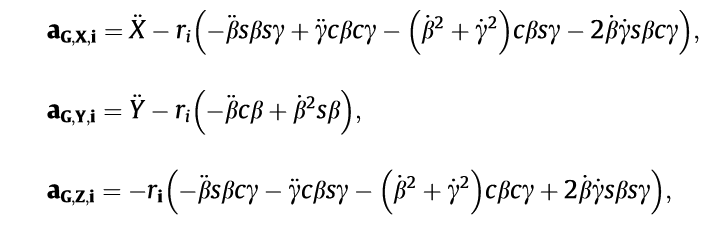

% Acceleration
a_x = dX - r_i * (db2 * sb * sg + dg2 * cb * cg - (db^2 + dg^2) * cb * sg - 2 * db * dg * sb * cg);
a_y = dY - r_i * (-db2 * cb + db^2 * sb);
a_z = - r_i * (db2 * sb * cg - db2 * cb * cg - (db^2 + dg^2) * cb * sg - 2* db *dg * sb * cg);

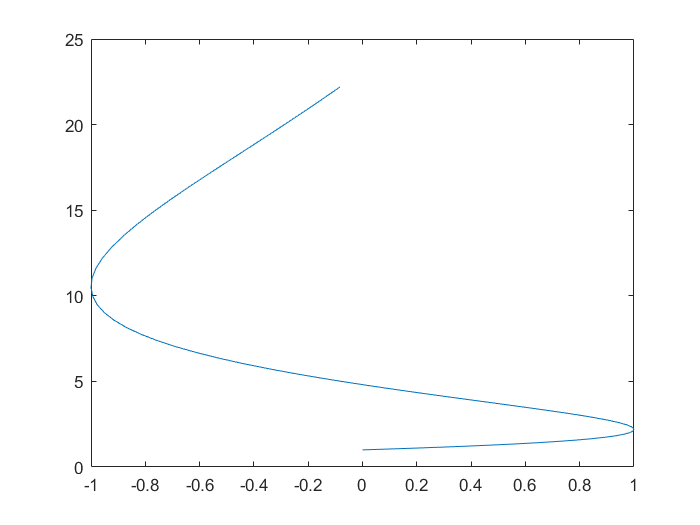

% Parametric curve
t = 0:0.1:2*pi;
X = sin(t);
Y = exp(t.^1/2);
plot(X, Y);

% plot(a_x, t)

# **Dynamics**